Time range:

tmax = 500; %Days

Initial values for S, I and R:

S0 = 1; %Initial suceptible percentage
I0 = 1.27e-6; %Initial infectious percentage
R0 = 0; %Initial recovered percentage

Birth rate and death rate parameters:

b = 1/2; %Birth rate
k = 1/3; %Death rate

Predict population dynamics for SIR model with Euler's method:

[S, I, R] = SIRmodel(tmax, S0, I0, R0, b, k) %Getting S, I, and R percentages from SIRmodel function

S =     0.5000    0.3750    0.2891    0.2325    0.1956    0.1713    0.1550    0.1439    0.1362    0.1309    0.1271    0.1244    0.1225    0.1211    0.1201    0.1194    0.1189    0.1185    0.1183    0.1181    0.1179    0.1178    0.1177    0.1177    0.1176    0.1176    0.1176    0.1176    0.1176    0.1176    0.1176    0.1176    0.1175    0.1175    0.1175    0.1175    0.1175    0.1175    0.1175    0.1175    0.1175    0.1175    0.1175    0.1175    0.1175    0.1175    0.1175    0.1175    0.1175    0.1175


I =     0.5000    0.4583    0.3915    0.3176    0.2486    0.1901    0.1430    0.1064    0.0786    0.0577    0.0423    0.0309    0.0225    0.0164    0.0119    0.0087    0.0063    0.0046    0.0033    0.0024    0.0017    0.0013    0.0009    0.0007    0.0005    0.0004    0.0003    0.0002    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


R =          0    0.1667    0.3194    0.4499    0.5558    0.6387    0.7020    0.7497    0.7852    0.8114    0.8306    0.8447    0.8550    0.8625    0.8680    0.8719    0.8748    0.8769    0.8784    0.8795    0.8803    0.8809    0.8813    0.8816    0.8819    0.8820    0.8821    0.8822    0.8823    0.8823    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8824    0.8825    0.8825    0.8825    0.8825    0.8825    0.8825    0.8825    0.8825    0.8825    0.8825    0.8825    0.8825


Plot S, I and R vs time:

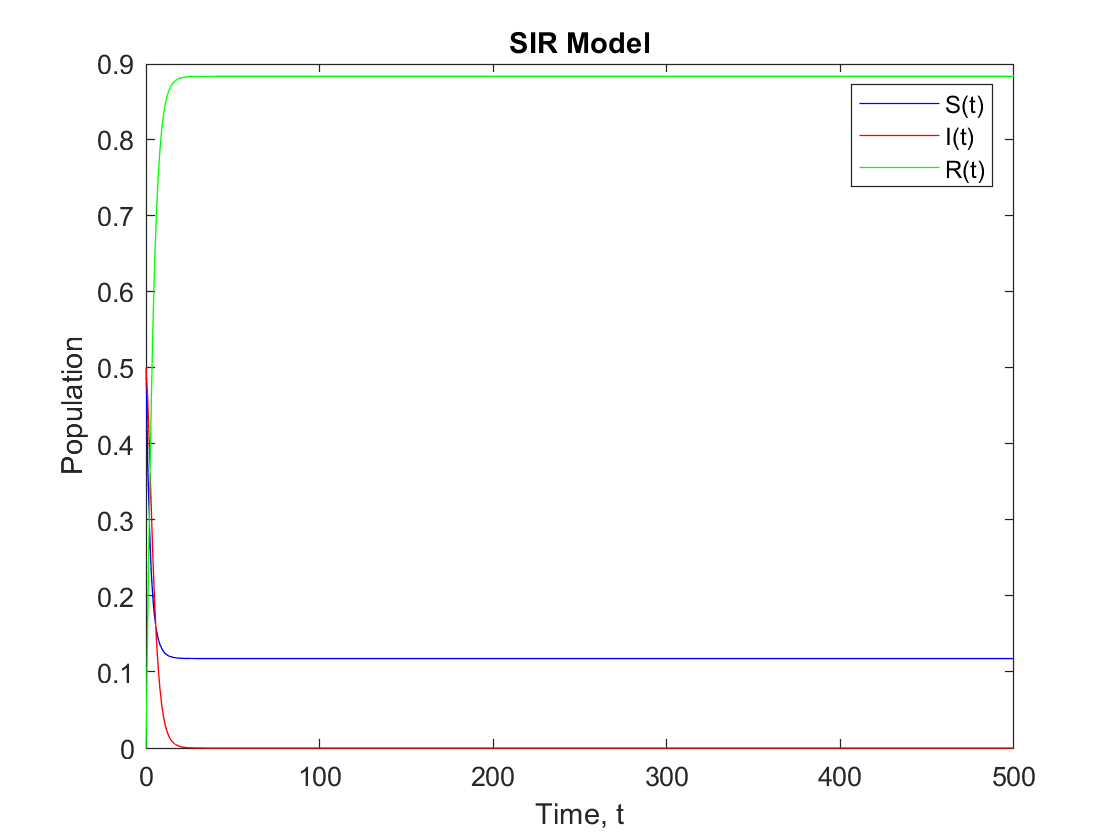

plot(0:tmax, S, 'b')

hold on

plot(0:tmax, I, 'r')
plot(0:tmax, R, 'g')

title('SIR Model')
legend('S(t)', 'I(t)', 'R(t)')

xlabel('Time, t')
ylabel('Population')

% xlim([0, 40])

hold off

This function defines S(t), I(t) and R(t) with the Euler's method.

function [S,I,R] = SIRmodel(tmax, S0, I0, R0, b, k)

    S = zeros(1, tmax); %Set-up an array with tmax number of values for each variable
    I = zeros(1, tmax);
    R = zeros(1, tmax);
    
    S(1) = S0; %Set-up initial values for each variable
    I(1) = I0;
    R(1) = R0;
    
    T(1) = 0; %Set-up initial value for the time

    Delta_t = 1; %Length of the step; the smaller the step, the more accurate the function is

    for n = 1:tmax %for-loop to calculate variables using euler's method
    
        T(n+1) = T(n) + Delta_t; %increments at which the time increases with

        S(n+1) = S(n) - b * S(n) * I(n) * Delta_t; %Approximations of our SIR values with respect to the increase of T
        I(n+1) = I(n) + (b * S(n) *I(n) - k * I(n)) * Delta_t;
        R(n+1) = R(n) + k * I(n) * Delta_t;
    
    end

end